
Length = 1;
Density = 1;
Tension = 1;

syms S(x,t) d r v L
assume(L>0)
T(x,t) = int(d/2*diff(S,t)^2,x,0,L);
V(x,t) = int(r/2*diff(S,x)^2,x,0,L);
A = T-V;
eqn = functionalDerivative(A,S) == 0;
eqn = simplify(eqn)/r;
eqn = subs(eqn,r/d,v^2);

syms U(x) V(t)
eqn2 = subs(eqn,S(x,t),U(x)*V(t));
eqn2 = eqn2/(U(x)*V(t));
tmp = children(eqn2);

syms C
eqn3 = tmp(1) == C;
eqn4 = tmp(2) == C;
V(t) = dsolve(eqn3,V(0)==0,t);
U(x) = dsolve(eqn4,U(0)==0,x);

V(t) = simplify(V(t),'Steps',50);
U(x) = simplify(U(x),'Steps',50);

p1 = setdiff(symvar(U(x)),sym([C,x]));
p2 = setdiff(symvar(V(t)),sym([C,v,t]));

eqn_bc = U(L) == 0;
[solC,param,cond] = solve(eqn_bc,C,'ReturnConditions',true)

$$solC = -\frac{k^{2}\,\pi^{2}}{L^{2}}$$

$$param = k$$

$$cond = C_{1}\neq 0\wedge 1\leq k\wedge k\in \mathbb{Z}$$

assume(cond)
S(x,t) = U(x)*V(t);
S = subs(S,C,solC);
S = subs(S,[L v],[Length sqrt(Tension/Density)]);

S = subs(S,[p1 p2],[1 1]);
S = simplify(S,'Steps',50);

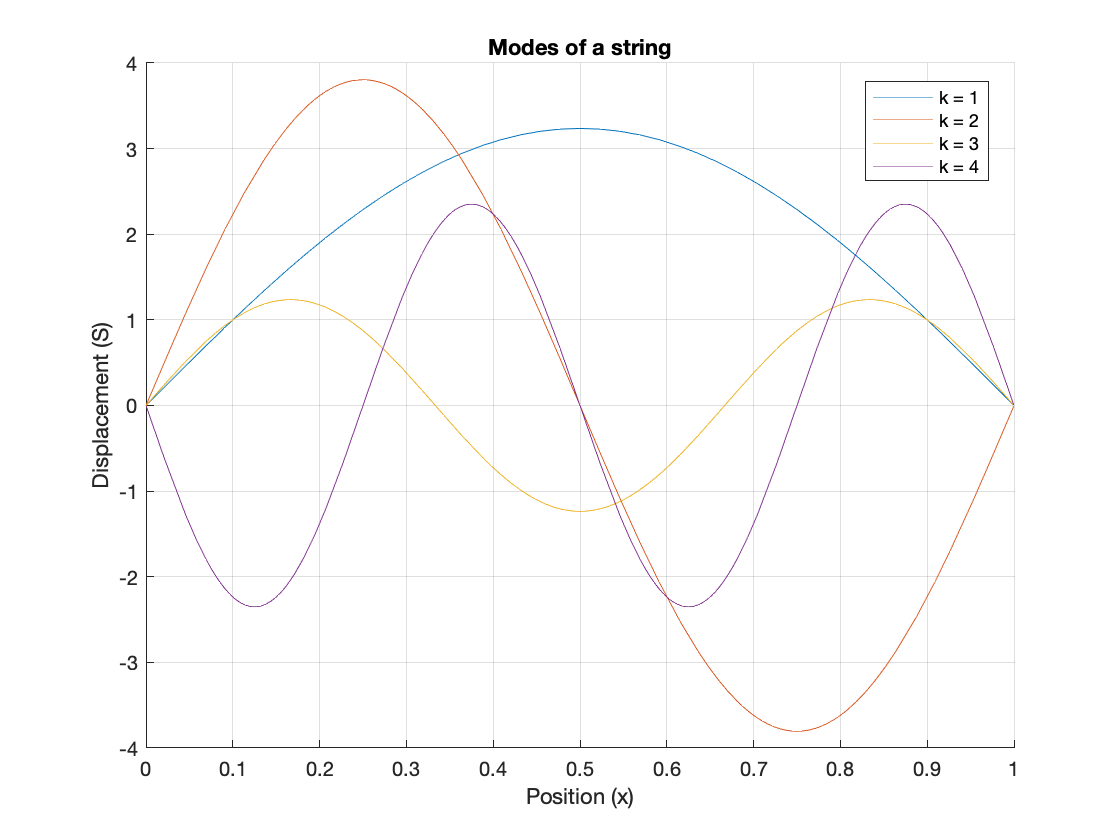


Splot(x) = S(x,0.3);
figure(1)
hold on
grid on
ymin = double(coeffs(Splot));
for i = 1:4
    yplot = subs(Splot,param,i);
    fplot(yplot,[0 Length])
end
ylim([-ymin ymin])
legend('k = 1','k = 2','k = 3','k = 4','Location','best')
xlabel('Position (x)')
ylabel('Displacement (S)')
title('Modes of a string')

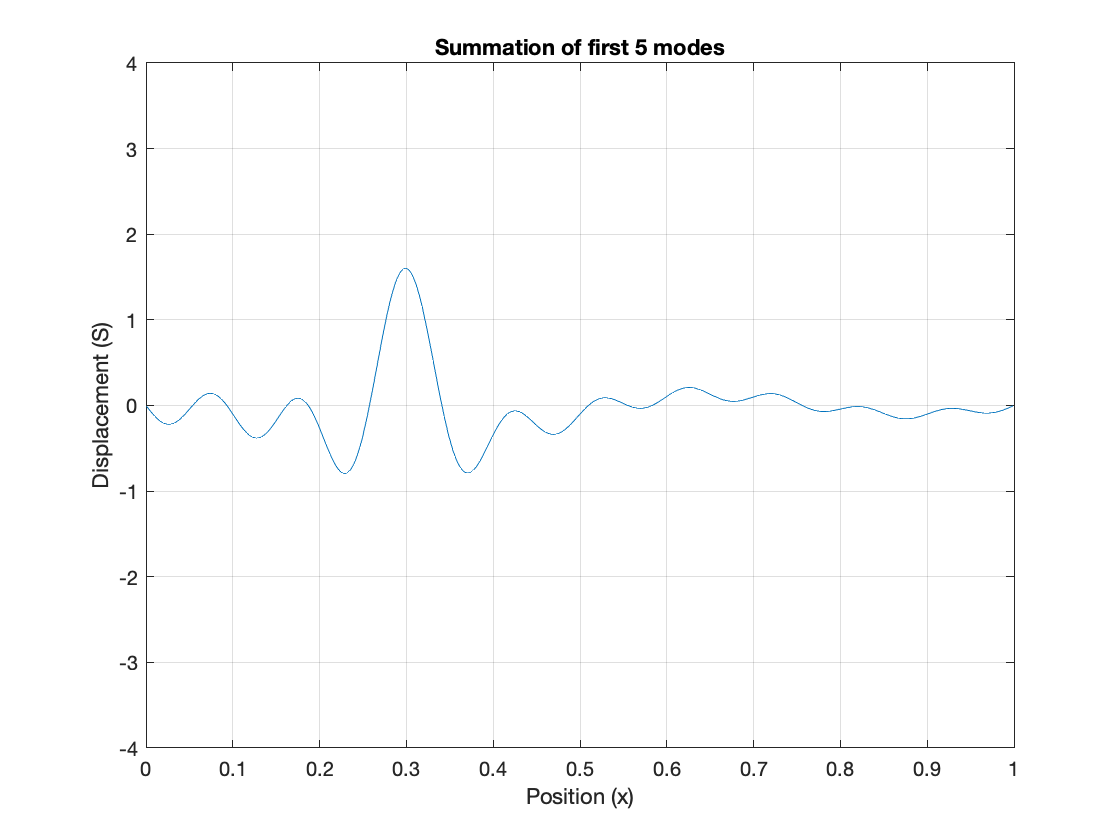


figure(2)
S5(x) = 1/20*symsum(S,param,5,20);
fplot(subs(S5,t,0.3),[0 Length])
ylim([-ymin ymin])
grid on
xlabel('Position (x)')
ylabel('Displacement (S)')
title('Summation of first 5 modes')